# Conditional Probability and Bayes Theorem

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

**Suggested Prework**

[Random Variables, Distributions, and Sampling](matlab:open('RandomVariablesSoln.mlx')) – Review the concepts of discrete and continuous random variables, probability distributions, sampling, and the central limit theorem.

**Before you get started:**

This live script is intended to be used with the code hidden or with the output inline. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code** or **Output inline**.  Alternately, select **Hide Code **using the icon   or **Output inline **using the icon   at the top right of the Live Editor pane.

 Even if the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

  **Try** identifies interactive activities that you will find in this script.  ***Reflect*** identifies conceptual questions related to the interactions.  

## Conditional Probability

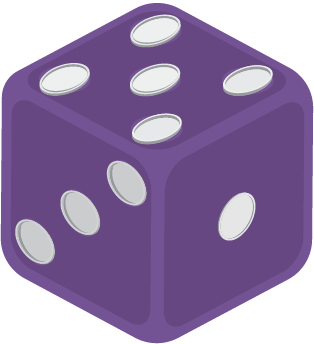                                                       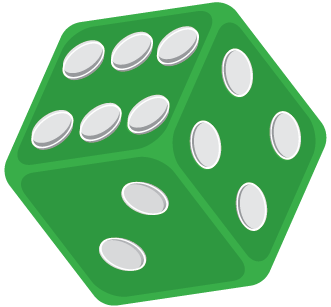

Suppose you roll two six-sided fair dice. What is the probability that the sum of the two rolls will be greater than or equal to 8, if you roll a 5 on the first die? 

Let's solve this problem by tabulating all the outcomes and visualizing our selected events as a subset of all outcomes in the sample space.

**Task a.** Use the slider to set the number of faces for the dice.

NumFaces =6;
SumMax = 2*NumFaces;

**Task b. **Select the event A of which you want to calculate the probability.

A = "D1";      v1 =6;

**Task c. **Select the event B to condition on; that is, an event that has already occurred or whose occurrence is presumed.

B = "S12less";      v2 =8;

**Task d. **Click the button **Show counts** to visualize the sample space of all combinations of the two die rolls, along with a representation of the selected outcomes.

 
figure("Position",[0 0 600 600]);
% Select the checkbox to display P(B|A) rather than explanation of the plot
VisualizeProbabilities(NumFaces,A,v1,B,v2,false); 

  **Try**

Set the drop-down and slider values appropriately to calculate the probabilities below. Use two six-sided dice.

- Given that you rolled a 4 on the second die, what is the probability that the sum of the two dice rolls is less than or equal to 7? (Assume that you cannot see the value of first die roll yet).

- If the sum of the two die rolls is greater than or equal to 8, what is the probability of having rolled a 5 on the first die?

- If you roll a 6 on the first die, what is the probability of rolling a 3 on the second one?

- Use the check box to compare $P(A|B)$ and $P(B|A)$.

 ***Reflect***

*Try several combinations of events A and B for the die rolls. Study the resulting tables, and reflect on the following questions:*

- *How does putting a condition on an event affect its sample space?*

- *What assumptions are we making (if any) about the individual die rolls in this visualization? (Refer to Try #3.) Are the assumptions sensible?*

- *Is* $P(A|B)$ *the same as* $P(B|A)$*? Can you explain why or why not?*

- *How are* $P(A|B)$ *and* $P(B|A)$* related?*

**Notation**

                    $P(A)$        Probability of event A

                    $P(B)$       Probability of event B

                    $P(A|B)$     Probability of A given that B has occurred (or is assumed to occur)

                                    
$$=\frac{P(A \bigcap B)}{P(B)}$$


## Bayes' Theorem

Bayes' theorem formulates the mathematical relationship between the two conditional probabilities $P(A|B)$ *and* $P(B|A)$. It is one of the most powerful theorems for probability, applied extensively in data science and machine learning. The theorem formalizes the process of updating knowledge based on evidence.

                    
$$P(A|B) = \frac{P(B|A)\times P(A)}{P(B)}$$


Alternative notations commonly used to state the theorem more directly invoke the notion of updating prior knowledge based on new evidence.

                    $P(\text{hypothesis}|\text{evidence}) = \frac{P(\text{evidence}|\text{hypothesis})\times P(\text{hypothesis})}{P(\text{evidence})}$   or      $P(H|E) = \frac{P(E|H)\times P(H)}{P(E)}$

In practice, the denominator term $P(E)$ is usually broken down into its component terms $P(E|H) \times P(H)$ and $P(E|\tilde{} H) \times P(\tilde{} H)$ for computation.

                    
$$P(H|E) = \frac{P(E|H) \times P(H)}{P(E|H) \times P(H) + P(E|\tilde{} H) \times P(\tilde{} H)}$$


**Example. **To detect a particular viral disease, the reported percentage of a positive test result among those who have the disease is 80%. The percentage of a negative test result when the disease is not present is reported to be 90%. What is the probability that you have the disease if the test result comes out to be positive?

These reported metrics, sensitivity and specificity, respectively, are based on controlled laboratory trials. One key piece of information to answer the question about your chances of having the disease, if tested positive, is the experts' knowledge about the prevalence rate of this disease–approximately how much percentage of the relevant population is estimated to have the disease? In this example, consider a prevalence rate of 30% in your locality.

**Task. **Verify that the slider settings below match the values given in the example. Click the **Run** button to use Bayes' theorem to compute the probability of having the disease if your test result is positive.

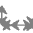

figure("Position",[0 0 500 500])
H      = 0.3;          % P(H)    -> prevalence of the disease in the population
E_H    = 0.8;          % P(E|H)  -> probability of seeing the evidence given the presence of disease 
E_NotH = 0.1;          % P(E|~H) -> probability of seeing the evidence given the absence of disease 
E      =  E_H*H + E_NotH*(1-H);                % P(E)    -> probability of the evidence (for example, getting a positive test result if the evidence is "positive")
 
H_E = BayesAreaPlot(H,E_H,E_NotH,true);         % P(H|E)  -> probability of having the disease given the evidence in form of a test result

  **Try**

- What is the probability of having the disease if your population's prevalence rate was around 5% and your test result is positive? Set the probability values using the sliders to find out. **Hint:** Use the code comments as a guide to set the values appropriately.

- What is the probability of having the disease if your population's prevalence rate was around 5% and your test result is negative? **Hint:** In this case, your "evidence" changes to "negative."

- Change the three probabilities to different values with the help of the sliders and study this geometric representation of Bayes' theorem.

 **Reflect**

- *What are the implications of the Bayes' theorem for making inferences based on data?*

- *What other real-life examples can you think of where Bayes' theorem might apply? Think in terms of a hypothesis, evidence, and prior knowledge.*

*In Machine Learning, Bayes' theorem is often represented as follows:*

                  $P(\text{model}|\text{data})=\frac{P(\text{data}|\text{model}) \times P(\text{model})}{P(\text{data})$*    or       *$P(\theta | x) = \frac{P(x | \theta) \times P(\theta)}{P(x)}$,* where *$\theta$ *represents model parameters and *$x$ *represents observed data*

                     $P(\text{data}|\text{model})$   $\rightarrow$      *likelihood*

                     $P(\text{model})$          $\rightarrow$      *prior*

                     $P(\text{model}|\text{data})$   $\rightarrow$      *posterior*

#### Spam Filter using Naive Bayes'

Suppose you manually filter your inbox of 1000 emails as spam or non-spam, keeping track of how frequently the word "win" occurs in each category. Suppose 500 of those were spam emails, and the word "win" occurred in 60 of the spam emails and 20 of the non-spam emails. What is the probability that a new incoming email is spam, given that it contains "win"? You can use Bayes' theorem to calculate this probability. 

                    
$$P(\text{spam}|\text{"win"}) = \frac{P(\text{"win"}|\text{spam}) \times P(\text{spam})}{P(\text{"win"})}$$


This probability indicates the *spamminess *or* spamicity* of the word "win". This forms the basis for a very simple email spam filter based on Bayes' theorem.

**Example. **Below is a very small sampling of spam and non-spam messages, a vocabulary of select words from the sample emails, and some additional test emails.

**                         Nonspam Messages                                                    Spam Messages                                 **

 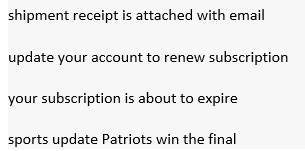     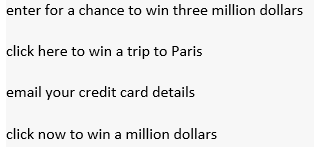

**Vocabulary extracted from samples** 

                    enter, click, win, million, details, email, credit, dollars, shipment, receipt, renew, account, subscription, update, expire

**Test messages to filter**

 

% Format the text as strings for analysis
spam    = ["enter for a chance to win three million dollars";...
           "click here to win a trip to Paris";...
           "email your credit card details";...
           "click now to win a million dollars"];

nonspam = ["shipment receipt is attached with email";...
           "update your account to renew subscription";...
           "your subscription is about to expire";...
           "sports update Patriots win the final"];

vocabulary = ["enter", "click", "win", "million", "details", "email", "credit", "dollars", "shipment", "receipt", "renew", "account", "subscription","update","expire"];
NumWords   = numel(vocabulary);

test    = ["click to enter details and claim lottery";...
           "add email in account to confirm membership";...
           "credit card about to expire update payment"];

**Task a.** Use the drop-down to calculate the spamicity of different words from the vocabulary. Start by choosing the word "win". Observe the intermediate steps.

word = vocabulary(8);
 

i. Count the number of spam emails containing the chosen word.

CountInSpam = nnz(contains(spam,word))              

CountInSpam = 2

ii.. Count the number of non-spam emails containing the chosen word.

CountInNonSpam = nnz(contains(nonspam,word))       

CountInNonSpam = 0

iii. Compute the probability $P(\text{Word}|\text{Spam})$. Many words do not occur in each category of sample messages. However, their probability of occurring in either category is not known to be zero. To avoid assigning zero probabilities, apply smoothing by adding one to the word count and adding the total number of words plus one to the denominator. This also ensures that the product term in Bayes' rule does not evaluate to zero because of one such word. This technique is called Laplace smoothing.

PWordGivenSpam    = CountInSpam + 1./(length(spam) + NumWords + 1)        

PWordGivenSpam = 2.0500

PWordGivenNonSpam =  CountInNonSpam + 1./(length(nonspam) + NumWords + 1)  % Similarly, compute P(Word|NonSpam).

PWordGivenNonSpam = 0.0500

iv. Compute the prior i.e. $P(\text{Spam})$ by calculating the proportion of sample messages that are spam.

PSpam    =  length(spam)./(length(spam) + length(nonspam))                

PSpam = 0.5000

PNonSpam = 1 - PSpam                                                       % Similarly, compute P(NonSpam)

PNonSpam = 0.5000

v. Apply Bayes' theorem to calculate the posterior i.e., $P(\text{Spam}|\text{Word})$

PSpamGivenWord =  PSpam*PWordGivenSpam./(PSpam*PWordGivenSpam + PNonSpam*PWordGivenNonSpam)     

PSpamGivenWord = 0.9762

You now have the spamicity values for the individual words. However, a spam filter cannot rely on just a single word to determine if a message is spam. If you make the "naive" assumption that each of these words occurs independent of every other word and that all words are equally important, the probability that an email is spam can be expressed using Bayes' theorem as below.


$$P(\text{spam}|W_1,W_2,\ldots, W_n) = \frac{P(\text{spam} \prod_i P(W_i|\text{spam})}{P(W_1,W_2,\ldots,W_n)}$$
                    

The code below computes the products $\displaystyle \prod_i P(W_i|\text{spam})$ and $\displaystyle \prod_i P(W_i|\text{nonspam})$  for all words in the vocabulary.

WordCountSpam       = @(x) nnz(contains(spam,vocabulary(x))) + 1;
PWordGivenSpam        = arrayfun(WordCountSpam,1:NumWords)./(length(spam) + NumWords + 1)

PWordGivenSpam =     0.1000    0.1500    0.2000    0.1500    0.1000    0.1000    0.1000    0.1500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500


WordCountNonSpam    = @(x) nnz(contains(nonspam,vocabulary(x))) + 1;
PWordGivenNonSpam     = arrayfun(WordCountNonSpam,1:NumWords)./(length(nonspam) + NumWords + 1)

PWordGivenNonSpam =     0.0500    0.0500    0.1000    0.0500    0.0500    0.1000    0.0500    0.0500    0.1000    0.1000    0.1000    0.1000    0.1500    0.1500    0.1000


**Task b. **Use the drop-down to select a test message and calculate the probability that it is spam. Observe the intermediate steps.

TestMessage = test(3) 

TestMessage = "credit card about to expire update payment"

i. Find which words from the entire vocabulary appear in the chosen test email.

WordsInMessage = @(x)contains(TestMessage,vocabulary(x));                                   
VocabIndex = arrayfun(WordsInMessage,1:numel(vocabulary))                                    

VocabIndex = 1×15 logical array
   0   0   0   0   0   0   1   0   0   0   0   0   0   1   1


ii. Use Bayes' theorem to calculate the posterior probability using only those words from `vocabulary` that appear in the email.

PSpamGivenAllWords = PSpam*prod(PWordGivenSpam(VocabIndex))./(PSpam*prod(PWordGivenSpam(VocabIndex))+(1-PSpam)*prod(PWordGivenNonSpam(VocabIndex)))

PSpamGivenAllWords = 0.2500

***Reflect***

- *Consider the third test email in the drop-down for *`testMessage`*. In the absence of Laplace smoothing, what would the output probability be?*

- *What is the implication of the "naive" (indpendently occurring and equally-important words) assumption made for this model?*

- *Applying Laplace smoothing to avoid zero probabilities was one practical consideration associated with using a sampling of pre-labeled emails to calculate the probabilities. What are some other practical considerations for applying such a spam filter  to your inbox?*

## 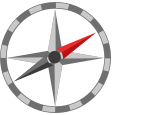 Further Exploration

For a practical introduction to data science with MATLAB, check out the following learning materials.

- [Data Science Specialization on Coursera](https://www.coursera.org/specializations/practical-data-science-matlab)

- [Machine Learning Onramp](https://matlabacademy.mathworks.com/R2021a/portal.html?course=machinelearning)

- [Regression Basics](https://www.mathworks.com/matlabcentral/fileexchange/93435-regression-basics)

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function VisualizeProbabilities(N,E1,v1,E2,v2,bayesFlag)
% VISUALIZEPROBABILITIES(N,E1,V1,E2,V2) illustrates conditional probability of die event E1,v1 given the event E2,v2
% by generating tables to ennumerate all possible outcomes for the two die rolls, along with a visualization of
% the event-specific outcomes and the corresponding sample space.
% E1 and E2 can be one of "D1", "D2", "S12less", and "S12more" representing the type of event.
% V1 and V2 are the corresponding numeric values for the event.
% BAYESFLAG is a logical value indicating whether the conditional
% probability P(E2|E1) should be included in the visualization.

%%%% Initialize variables. %%%%
f = 1:N;                            % a vector going from 1 to number of faces
S = f+f';                           % matrix representing the sum of die roll values
map = [0.9 0.9 0.9;                 % color map for viewing the outcomes and sample space
    1   1   1;
    0.8  1  0.8];

% Initialize a tiled layout for plotting.
T = tiledlayout(2,2,"Padding","compact");
E1str = inputname(2);
E2str = inputname(4);

%%%% Create and plot the color matrix M# to illustrate the outcomes related to each event. %%%%
% 1. Generate event E1 outcomes matrix
t1 = nexttile(T,1);
M1 = zeros(N);
if E1 == "D1"
    try
        test = M1(v1,:); %#ok<NASGU> 
        M1(v1,:) = 2;
    catch
        warning("Event "+ E1str +", Die 1 value exceeds the number of faces. Setting it to " + N)
        v1 = N;
        M1(v1,:) = 2;
    end
elseif E1 =="D2"
    try
        test = M1(:,v1); %#ok<NASGU> 
        M1(:,v1) = 2;
    catch
        warning("Event "+ E1str +", Die 2 value exceeds the number of faces. Setting it to " + N)
        v1 = N;
        M1(:,v1) = 2;
    end
elseif E1 == "S12less"
    M1(S<=v1)=2;
else
    M1(S>=v1)=2;
end
ViewDiceOutcomes(M1,map,S);

% 2. Generate event E2 outcomes matrix
t2 = nexttile(T,2);
M2 = zeros(N);
if E2 == "D1"
    try
        test = M2(v2,:); %#ok<NASGU> 
        M2(v2,:) = 2;
    catch
        warning("Event " + E2str + ", Die 1 value exceeds the number of faces. Setting it to " + N)
        v2 = N;
        M2(v2,:) = 2;
    end
elseif E2 =="D2"
    try
        test = M2(:,v2); %#ok<NASGU> 
        M2(:,v2) = 2;
    catch
        warning("Event " + E2str + ", Die 2 value exceeds the number of faces. Setting it to " + N)
        v2 = N;
        M2(:,v2) = 2;
    end
elseif E2 == "S12less"
    M2(S<=v2)=2;
else
    M2(S>=v2)=2;
end
ViewDiceOutcomes(M2,map,S);

% 3. Generate matrices for E1 given E2 outcomes(M3), and E2 given E1 outcomes(M3BACK)
t4 = nexttile(T,4);
P3 = M1 & M2;
P2 = logical(M2);
P2Back = logical(M1);
M3 = ones(N);
M3Back = M3;
M3(P2) = 0;
M3Back(P2Back) = 0;
M3(P3) = 2;
M3Back(P3) = 2;
ViewDiceOutcomes(M3,map,S);

%%%% Title the outcome tables with their respective probability fractions. %%%%
% 1. Event A title
event = nnz(M1);
total = numel(M1);
str = "P("+E1str+") = " + compose("$\\frac {%u}{%u}$",event,total);
title(t1,str,"Interpreter","latex");

% 2. Event B title
event = nnz(M2);
total = numel(M2);
str = "P("+E2str+") = " + compose("$\\frac {%u}{%u}$",event,total);
title(t2,str,"Interpreter","latex");

% 3. Event E1 given E2 title
event = nnz(M3==2);
total = event + nnz(M3==0);
str = compose("P("+E1str+"$\\vert$"+E2str+") =  $\\frac {%u}{%u}$",event,total);
title(t4,str,"Interpreter","latex");

%% Explain the colors and table values by plotting text on the third tile if BAYESFLAG is false, or plot the outcome of E2 given E1 if BAYESFLAG is true.
t3 = nexttile(T,3);
if ~bayesFlag
    text(0,0.9,["D1 \rightarrow Die 1 roll value"; ...
        "D2 \rightarrow Die 2 roll value"],"FontSize",12);
    text(0,0.7,"Numbers in cells: D1+D2","Color","b","FontSize",12)
    tStr = sprintf("\\fontsize{9}{P(E) = }" + ...
        "\\fontsize{12}{^{\\color{green}green}/_" + ...
        "{({\\color{green}green}+{\\color{gray}gray})}}");
    text(0,0.4,tStr,"FontSize",16);
    axis off
else
    ViewDiceOutcomes(M3Back,map,S);
    event = nnz(M3Back==2);
    total = event + nnz(M3Back==0);
    str = compose("P("+E2str+"$\\vert$"+E1str+") =  $\\frac {%u}{%u}$",event,total);
    title(t3,str,"Interpreter","latex");
end

end

function I = ViewDiceOutcomes(M,map,S)
% VIEWDICEOUTCOMES(M,MAP,S) displays a scaled image
% using the indices in matrix M and the colormap MAP.
% S is a matrix containing values to be printed inside each cell.
% The visualization labels and colors are optimized to display outcomes for
% two independent die rolls.

% Generate the x and y coordinates for the center of the cells (from 1 to N).
N1 = size(M,1);
N2 = size(M,2);
x = repmat(1:N2,N1,1);
y = repmat(1:N1,N2,1)';

% Plot the input matrix as an indexed image with a color map (M,MAP).
I = imagesc(M);
colormap(map)
caxis([0 2])

% Overlay the image with the sum of dice matrix (S).
text(x(:),y(:),string(S),"HorizontalAlignment","Center","FontSize",9,"FontName","Cambria","Color",[0.5 0.5 1])

% Set the axes properties for readability.
ax = gca;
ax.FontSize = 10;
ax.FontWeight = "bold";
ax.TickLength = [0 0];
ax.XAxis.MinorTickValues = 0.5:1:N2;
ax.YAxis.MinorTickValues = 0.5:1:N1;
ax.MinorGridLineStyle = "-";
grid on
grid minor
ax.GridLineStyle = "none";
xticks(ax,1:N2);
yticks(ax,1:N1);
ytickangle(ax,90);

% Label the axes.
xlabel(ax,"D2")
ylabel(ax,"D1")

end


function H_E = BayesAreaPlot(H,E_H,E_NotH,animFlag)
% BAYESAREAPLOT(H,E_H,E_NOTH,ANIMFLAG) displays a geometric visualization
% of Bayes' theorem. 
% H is the prior probability of the hypothesis.
% E_H is the probability of the evidence given the hypothesis.
% E_NOTH is the probability of the evidence contrary to the hyothesis.
% ANIMFLAG is a logical value to indicate whether or not to animate the
% plot.

% Initialize a tiled layout for visualizing Bayes' rule.
tiledlayout(6,1,"TileSpacing","compact","Padding","compact");
t1 = nexttile([5,1]);
if exist("people.png","file")
    filepath = which("people.png");
    I = imrotate(imread(filepath),180);
    [sz1, sz2, ~] = size(I);
    image(I);
    alpha(0.25);
else
    sz1 = 1;
    sz2 = 1;
end
set(gca,"YDir","normal")
axis off

% Calculate the numerator and denominator of Bayes' rule, and the posterior
% probability.
num = H.*E_H;
den = E_H*H + E_NotH*(1-H);
H_E = num./den;

% Switch to the second tile to initialize the plot for the posterior probability
t2 = nexttile([1,1]);
set(gca,"YColor",[1 1 1],"FontSize",11,"YLim",[0 1],"XLim",[0 den],"XColor",[0.4 0.4 0.8],"TickLength",[0 0],"XTick",[0 den],"xticklabels",[0 1]);
xlabel("P(H|E)");

% Set up patch vertices and colors for the first tile. These patches show the
% different components of the Bayes' formula.
vert0 = [0 sz2 sz2 0; 0 0 sz1 sz1]';
vert1 = [0 sz2*H sz2*H 0; 0 0 sz1 sz1]';
vert2 = [sz2*H sz2 sz2 sz2*H; 0 0 sz2 sz1]';
vert3 = [0 sz2*H sz2*H 0; sz1*E_H sz1*E_H 0 0]';
vert4 = [sz2*H sz2 sz2 sz2*H; 0 0 sz1*E_NotH sz1*E_NotH]';
vert  = cat(3,vert0,vert1,vert2,vert3,vert4);
cdata = [0.99 0.99 0.99; 0.8 0 0.3; 0.1 0.9 0; 0.1 0.1 0.5; 0.1 0.1 0.5];

% Plot the patches on the first tile.
axes(t1)
hold on
for k = 1:size(vert,3)
    if animFlag
        pause(0.5)
    end
    patch(vert(:,1,k),vert(:,2,k),cdata(k,:),"FaceAlpha",0.2,"EdgeColor","none");
    drawnow
end

% Annotate the patches with labels for the prior and likelihood
% probabilities.
arrowColor = [0.5 0.5 0.5];
textColor = [1 1 1];
pos = t1.Position;
if animFlag
    pause(0.5)
end
annotation("doublearrow",[pos(1),pos(1)+pos(3).*H],[pos(2),pos(2)]-0.01,"Head1Length",6,"Head2Length",6,"Color",arrowColor);
text(0.01,E_H./2,"P(E|H)","Parent",t1,"Units","normalized","HorizontalAlignment","left","Color",textColor);
annotation("doublearrow",[pos(1),pos(1)]-0.01,[pos(2),pos(2)+pos(4).*E_H],"Head1Length",6,"Head2Length",6,"Color",arrowColor);
text(H./2,0.02,"P(H)","Parent",t1,"Units","normalized","HorizontalAlignment","center","Color",textColor);
annotation("doublearrow",[pos(1)+pos(3).*H,pos(1)+pos(3)],[pos(2),pos(2)]-0.01,"Head1Length",6,"Head2Length",6,"Color",arrowColor);
text(H + (1-H)./2,0.02,"P(~H)","Parent",t1,"Units","normalized","HorizontalAlignment","center","Color",textColor);
annotation("doublearrow",[pos(1)+pos(3),pos(1)+pos(3)]+0.01,[pos(2),pos(2)+pos(4).*E_NotH],"Head1Length",6,"Head2Length",6,"Color",arrowColor);
text(1-0.01,E_NotH./2,"P(E|~H)","Parent",t1,"Units","normalized","HorizontalAlignment","right","Color",textColor);
hold off

% Set up patch vertices and colors for the second tile to display the posterior probability.
vert0 = [0 den den 0; 0 0 1 1]';
vert1 = [0 num num 0; 0 0 1+num 1+num]';
vert2 = [num den den num; 0 0 1 1]';
vert = [vert1;vert2;vert0];
faces = reshape(1:length(vert),4,[])';
cdata = cdata(2:4,:);

% Plot the patches on the second tile and set up axis ticks to show the
% computed value from Bayes' theorem.
axes(t2)
patch("Vertices",vert,"Faces",faces,"FaceVertexCData",cdata,"FaceColor","flat","FaceAlpha",0.4,"EdgeColor","none");
set(gca,"XTick",[0 num den],"xticklabels",[0 round(H_E,2) 1]);
drawnow

end